%compare beam squint compensation between different method
clc;
clear all;
close all;

B = 1e9.*[30,40,60];

%% system parameters
Sysparam = struct();

Sysparam.Nt = 720;
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 3e11;%carrier frequency 
%Sysparam.f = 30e9; %bandwidth 
Sysparam.K = 129;  %number of sub-carriers
Sysparam.M = 36; %number of TTDs for each RF chain
Sysparam.N = Sysparam.Nt/Sysparam.M; %number of PSs for each TTD
Sysparam.L = 1 ; % number of paths equals to number of RF chains
% compute discrete time-delay values
%Sysparam.Q = 16; % number of fixed TTD element 
Sysparam.tmax = (1e-12)*500;
%Sysparam.T = Sysparam.tmax*(0:1:Sysparam.Q-1)/(Sysparam.Q-1);


%% simulation parameters
Simparam = struct();
Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;
Simparam.Niter = 100; %channel realizations
Simparam.phi = 0.2951*pi*ones(Sysparam.L,1);%AoD;
SpatialDirection = sin(Simparam.phi)

SpatialDirection = 0.7999

Nloop = 50;

%% 
for i = 1:length(B)
Sysparam.f = B(i); %bandwidth
%% Sub-carrier frequencies
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 
%Generate wideband channel
%H = WidebandChannel(Sysparam,Simparam);
%[G1,G2k,x2,t2] = fixPSdesignTTD(Sysparam,Simparam); %Tan design
[PS,TTD,x,t] = jointPSandTTD(Sysparam, Simparam); % joint delay and phase precoding
%[S,F2k,D,~] = DynamicSubarray(Sysparam,Simparam,H,Nloop); %Dynamic subarray method

for l = 1:Sysparam.L
    a(:,l) = arrayResponse(sin(Simparam.phi(l)),Sysparam.Nt);
    for k = 1:Sysparam.K
         b(:,k,l) = arrayResponse(Sysparam.xi(k)*sin(Simparam.phi(l)),Sysparam.Nt);
         arrayGain(k,l,i) = abs(a(:,l)'*b(:,k,l));
         Compensated1(k,l,i) = abs((PS*TTD(:,l,k))'*b(:,k,l));
         %Compensated2(k,l,i) = abs((G1*G2k(:,l,k))'*b(:,k,l));          
         %Compensated3(k,l,i) = abs((S*F2k(:,l,k))'*b(:,k,l));
    end
end
clear a b ;
end 

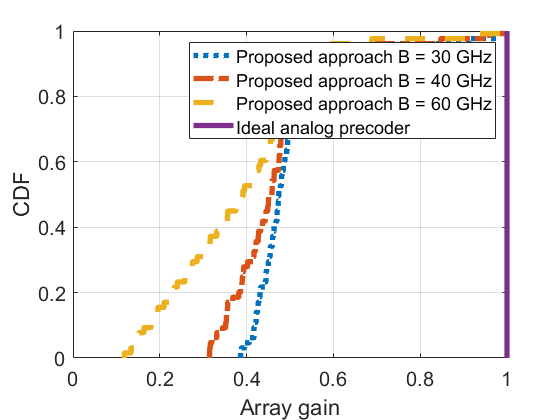

close all;
figure(1)
f1 = cdfplot(Compensated1(:,:,1));
set(f1,'LineWidth',4,'LineStyle',':','Marker','none');
hold on
f2 = cdfplot(Compensated1(:,:,2));
set(f2,'LineWidth',4,'LineStyle','-.','Marker','none');
hold on
f3 = cdfplot(Compensated1(:,:,3));
set(f3,'LineWidth',4,'LineStyle','--','Marker','none');
hold on
f4 = cdfplot(ones(Sysparam.K,1));
set(f4,'LineWidth',4,'LineStyle','-','Marker','none');
legend('Proposed approach B = 30 GHz','Proposed approach B = 40 GHz','Proposed approach B = 60 GHz','Ideal analog precoder')
xlabel('Array gain')
ylabel('CDF')
title('')